data11 = struct with fields:
    wavelength: [201×1 double]
          data: [201×1 double]
       comment: {'grid gray'}
       dFormat: 'double'


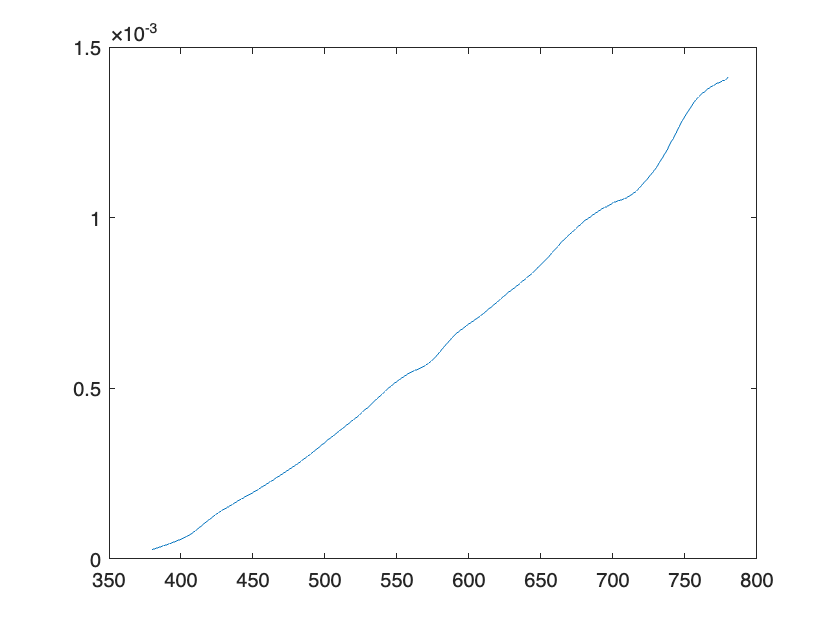

R = 0.2565

rho = 0.9900

E = 0.8138

ans = "purplepeople eater"

ans = 1.6114

halogenEMatrixWhite =     2.9425    4.5178    9.8942   11.9288   12.2989    7.8709    2.9528    2.6643
    3.0207    6.7785   22.4852   45.8673   39.4918   13.6251    3.5971    2.9294
    3.5266    4.7101    6.7379    7.7533    6.7932    5.4895    4.7259    2.2309


halogenEMatrixGrey =     1.6114    2.5040    5.4136    6.7247    6.9015    4.4337    1.6626    1.4762
    1.6347    3.7946   12.6714   26.0581   22.4382    7.8064    2.0548    1.6553
    1.9216    2.6084    3.7830    4.3866    3.8666    3.0934    2.6609    1.2673


[halogenEMatrixWhite, halogenEMatrixGrey] = fillE()

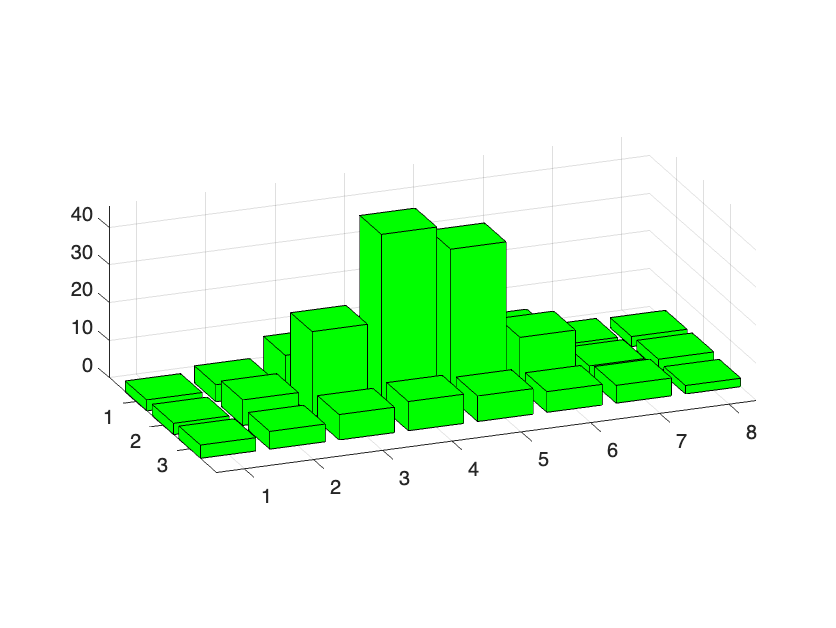

bar3(halogenEMatrixWhite,'g')

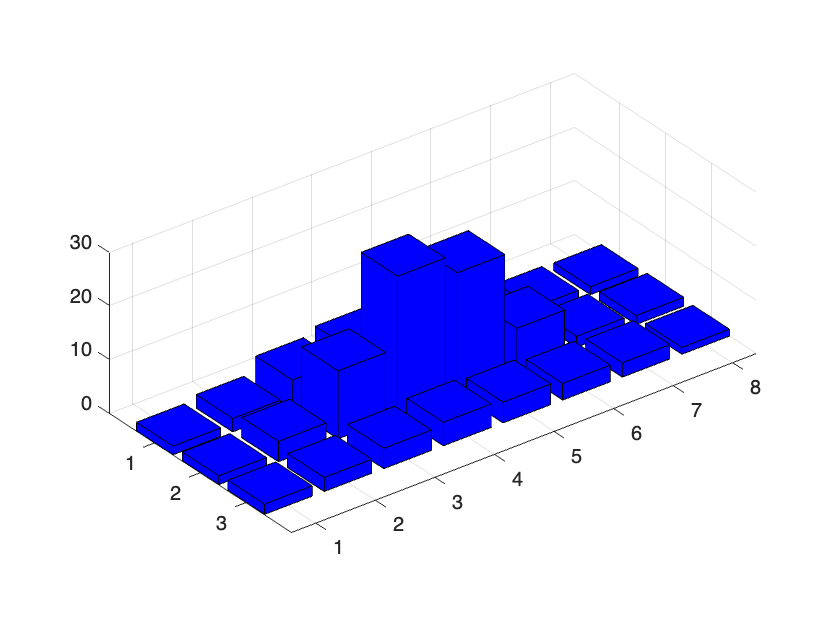

bar3(halogenEMatrixGrey,'b')

function irradiance_est = irradiance(filename, rho)
    dict = load(filename);
    R = trapz(dict.wavelength, dict.data);
    irradiance_est = pi / rho * R;

end

function [EMatrixWhite, EMatrixGrey] = fillE()

    
    EMatrixWhite = zeros(3, 8);
    EMatrixGrey = zeros(3, 8);
    
    for i = 1:3
        for j = 1:8
            filenameGray = "grid" + int2str(i) + int2str(j) + "_grayCard.mat";
            filenameWhite = "grid" + int2str(i) + int2str(j) + "_whiteCard.mat";
           
            
            EMatrixWhite(i, j) = irradiance(filenameWhite, 0.99);
            EMatrixGrey(i, j) = irradiance(filenameGray, 0.5);
        end
    end

end
